# Minimizing a Mathematical Function

% 创建优化变量
x3 = optimvar("x",2,1,"LowerBound",0);

% 设置求解器的初始起点
initialPoint.x = zeros(size(x3));

% 创建问题
problem = optimproblem;

% 定义问题目标
problem.Objective = (x3(1)-3)^2 + (x3(2)-2)^2;

% 定义问题约束
problem.Constraints.constraint1 = 26 - (x3(1)-5)^2 - x3(2)^2 >= 0;
problem.Constraints.constraint2 = 10-4*x3(1)-x3(2) >= 0;

% 显示问题信息
show(problem);


  OptimizationProblem : 

	Solve for:
       x

	minimize :
       ((x(1) - 3).^2 + (x(2) - 2).^2)


	subject to constraint1:
       ((26 - (x(1) - 5).^2) - x(2).^2) >= 0

	subject to constraint2:
       -4*x(1) - x(2) >= -10

	variable bounds:
       0 <= x(1)
       0 <= x(2)




% 求解问题
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint);

将使用 lsqnonlin 求解问题。

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



% 显示结果
solution

solution = 包含以下字段的 struct :
    x: [2×1 double]


reasonSolverStopped

reasonSolverStopped =     OptimalSolution


objectiveValue

objectiveValue = 0.9412


% 清除变量
clearvars x3 initialPoint reasonSolverStopped objectiveValue

## Evaluate the objective function and constraints

obj = problem.Objective

obj =   Quadratic OptimizationExpression

    x(1)^2 + x(2)^2 - 6*x(1) - 4*x(2) + 13


con1 = problem.Constraints.constraint1

con1 =   Quadratic OptimizationConstraint

    ((26 - (x(1) - 5).^2) - x(2).^2) >= 0


con2 = problem.Constraints.constraint2

con2 =   Linear OptimizationConstraint

    -4*x(1) - x(2) >= -10


x1 = linspace(-5,15,100);
x1 = meshgrid(x1);
x2 = x1';

zobj = zeros(size(x1));
zcon1 = zobj;
zcon2 = zobj;
for k=1:numel(x1)
xs.x = [x1(k);x2(k)];
zobj(k) = obj.evaluate(xs);
zcon1(k) = con1.infeasibility(xs);
zcon2(k) = con2.infeasibility(xs);
end

## Make visualization of the objective, constraints and solution together

contour(x1,x2,zobj)
ubx=15;
uby=15;
hold on
patch([0,ubx,ubx,0],[0,0,uby,uby],[0.75,0,0],...
    "EdgeColor","none",'FaceAlpha',0.3)
idx1 = zcon1 == 0;
p1 = plot(alphaShape(x1(idx1),x2(idx1),1))

p1 =   Patch - 属性:

    FaceColor: [0.6039 0.8039 0.1961]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [3888×3 double]
     Vertices: [1996×2 double]

  显示 所有属性


idx2 = zcon2 == 0;
p2 = plot(alphaShape(x1(idx2),x2(idx2),1))

p2 =   Patch - 属性:

    FaceColor: [0.6039 0.8039 0.1961]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [6088×3 double]
     Vertices: [3150×2 double]

  显示 所有属性


p1.EdgeColor = "none"

p1 =   Patch - 属性:

    FaceColor: [0.6039 0.8039 0.1961]
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [3888×3 double]
     Vertices: [1996×2 double]

  显示 所有属性


p2.EdgeColor = "none"

p2 =   Patch - 属性:

    FaceColor: [0.6039 0.8039 0.1961]
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [6088×3 double]
     Vertices: [3150×2 double]

  显示 所有属性


p1.FaceColor = "green"

p1 =   Patch - 属性:

    FaceColor: [0 1 0]
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [3888×3 double]
     Vertices: [1996×2 double]

  显示 所有属性


p2.FaceColor = "blue"

p2 =   Patch - 属性:

    FaceColor: [0 0 1]
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [6088×3 double]
     Vertices: [3150×2 double]

  显示 所有属性


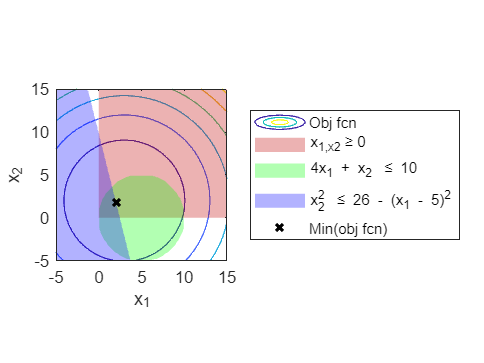

p1.FaceAlpha = 0.3;
p2.FaceAlpha = 0.3;
plot(solution.x(1),solution.x(2),"kx","LineWidth",2)
hold off

xlabel("x_1"),ylabel("x_2")
legend("Obj fcn",....
       "x_1,x_2\geq0",...
       "4x_1 + x_2 \leq 10",...
       "x_2^2 \leq 26 - (x_1 - 5)^2",...
       "Min(obj fcn)",...
       "location","EO")